% demos for ch07

## sparse signal recovery demo

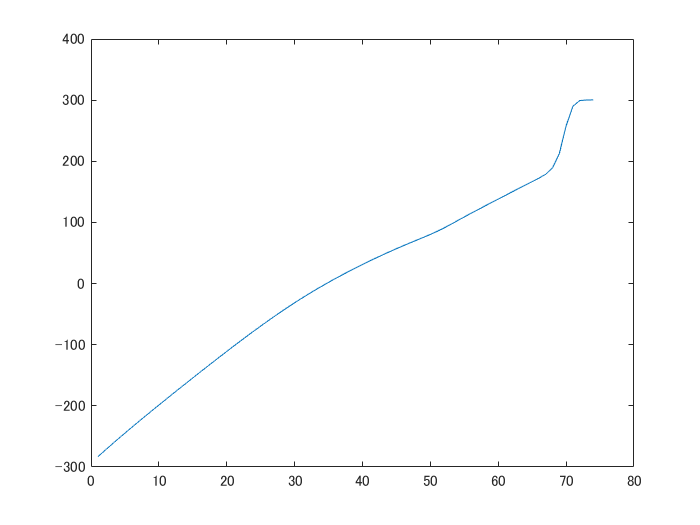

clear; close all; 

d = 512; % signal length
k = 20;  % number of spikes
n = 100; % number of measurements
%
% random +/- 1 signal
x = zeros(d,1);
q = randperm(d);
x(q(1:k)) = sign(randn(k,1)); 

% projection matrix
A = unitize(randn(d,n),1);
% noisy observations
sigma = 0.005;
e = sigma*randn(1,n);
y = x'*A + e;

[model,llh] = rvmRegEm(A,y);
plot(llh);

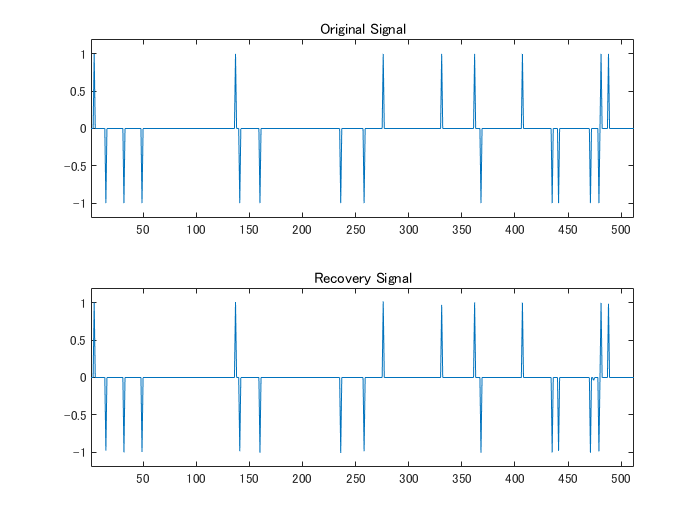


m = zeros(d,1);
m(model.index) = model.w;

h = max(abs(x))+0.2;
x_range = [1,d];
y_range = [-h,+h];
figure;
subplot(2,1,1);plot(x); axis([x_range,y_range]); title('Original Signal');
subplot(2,1,2);plot(m); axis([x_range,y_range]); title('Recovery Signal');